clear
close all
clc
addpath 'C:\GitHub\MatLab\Diplomka\Resources'
addpath 'C:\GitHub\MatLab\Diplomka\stability-tests\'

## Sections

crossSectionsSet.import = importdata("sectionsSet.mat");
crossSectionsSet.A = table2array(crossSectionsSet.import.RHS(:,"A"));
crossSectionsSet.Iy = table2array(crossSectionsSet.import.RHS(:,"I_y"));
crossSectionsSet.Iz = table2array(crossSectionsSet.import.RHS(:,"I_z"));
crossSectionsSet.Ip = table2array(crossSectionsSet.import.RHS(:,"I_t"));

sections.id = [6;9;7;8;3;5;6;4;4;3;1;5];

for i = 1:size(sections.id,1)
    sections.A(i,1)  = crossSectionsSet.A(sections.id(1));
    sections.Iy(i,1) = crossSectionsSet.Iy(sections.id(1));
    sections.Iz(i,1) = crossSectionsSet.Iz(sections.id(1));
    sections.Ix(i,1) = crossSectionsSet.Ip(sections.id(1));
    sections.E(i,1)  = 210*10^9;
    sections.v(i,1)  = 0.3;
end

ndisc = 7

ndisc = 7

## Nodes

width = 2.9;
length = 2.9;
height = 3;
topHeight = 20;
nbricks = 7;
nodes.x = [[0;length;length;0];kron(ones(nbricks,1),[length/2;length;length/2;0;0;length;length;0])];                            % x coordinates of nodes
nodes.y = [[0;0;width;width];kron(ones(nbricks,1),[0;width/2;width;width/2;0;0;width;width])];                              % y coordinates of nodes
nodes.z = [0;0;0;0];
for i = 1:nbricks
    nodes.z  = [nodes.z; [height/2;height/2;height/2;height/2;height;height;height;height] + (i-1) .* [height;height;height;height;height;height;height;height]];
end
nodes.z((nbricks)*7+4:(nbricks+1)*7+4) =[topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight;topHeight;topHeight;topHeight]; % z coordinates of nodes
nnodes = numel(nodes.x); 

## Supports

kinematic.x.nodes = [1;2;3;4];              % node indices with restricted x-direction displacements
kinematic.y.nodes = [1;2;3;4];              % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3;4];              % node indices with restricted z-direction displacements
kinematic.rx.nodes = [];                    % node indices with restricted x-direction displacements
kinematic.ry.nodes = [];                   % node indices with restricted y-direction displacements
kinematic.rz.nodes = [];                    % node indices with restricted z-direction displacements

nodes.dofs = true(nnodes,6);                % no kinematic boundary conditions
nodes.dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
nodes.dofs(kinematic.rx.nodes,4) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.ry.nodes,5) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.rz.nodes,6) = false;    % mark prevented movement in z-direction

## Beams

modulNodes1 = [1;2;3;4; 1;5;2;5;2;6;3;6;3;7;4;7;4;8;1;8; 9;10;11;12  ];   % elements starting nodes
beams.nodesHead = (reshape(kron(modulNodes1', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(modulNodes1))*8);
% beams.nodesHead = modulNodes1;
modulNodes2 = [9;10;11;12; 5;10;5;9;6;11;6;10;7;12;7;11;8;9;8;12; 10;11;12;9  ];   % elements ending nodes
beams.nodesEnd = (reshape(kron(modulNodes2', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(modulNodes2))*8);
% beams.nodesEnd = modulNodes2;
nr = numel(beams.nodesHead);

### Beams sections

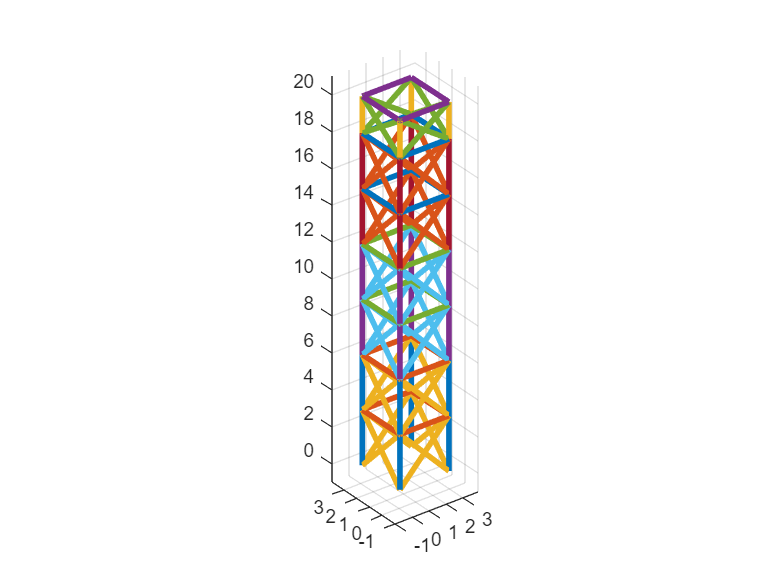

beams.disc      = ones(nr,1)*ndisc;
modulElemGroup = [1;1;1;1; 3;3;3;3;3;3;3;3;3;3;3;3;3;3;3;3;    2;2;2;2];
pocetOpakovani = 4;
opakovani = repmat(modulElemGroup, 1, pocetOpakovani);
posuny = (0:pocetOpakovani-1) * 3;
elemGroup = opakovani + posuny;
elemGroup = [elemGroup(:, 1); elemGroup(:, 1); elemGroup(:, 2);  % První sloupec třikrát
          elemGroup(:, 2); elemGroup(:, 3); elemGroup(:, 3);  % Druhý sloupec třikrát
          elemGroup(:, end)];
beams.sections = elemGroup;
uniqueSections = unique(beams.sections);

% Mapování barev na ID průřezů
colorMap = lines(numel(uniqueSections));


for i = 1:numel(uniqueSections)
    idx = beams.sections == uniqueSections(i);
    plot3([nodes.x(beams.nodesHead(idx)) nodes.x(beams.nodesEnd(idx))]', ...
          [nodes.y(beams.nodesHead(idx)) nodes.y(beams.nodesEnd(idx))]',...
          [nodes.z(beams.nodesHead(idx)) nodes.z(beams.nodesEnd(idx))]',...
          'Color', colorMap(i, :), 'LineWidth', 3);
    hold on;
end
hold on;
ng = max(max(beams.sections));
% scatter3(nodes.x, nodes.y, nodes.z, 'black', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on

## Loads

% loads.x.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with x-direction forces
% loads.x.value = [-10000;-10000;-10000;-10000];             % magnitude of the x-direction forces
% loads.y.nodes = reshape((repmat([1,2], nbricks, 1) + (1:nbricks)'*8).',1,[])';          % node indices with y-direction forces
% loads.y.value = ones(nbricks*2,1)*0.25;          % magnitude of the y-direction forces 
% loads.z.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with z-direction forces
% loads.z.value = [-10000;-10000;-10000;-10000];
loads.y.nodes = reshape((repmat([1,2], nbricks, 1) + (1:nbricks)'*8).',1,[])';             % node indices with x-direction forces
loads.y.value = ones(nbricks*2,1)*0.25;             % magnitude of the x-direction forces
loads.x.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with y-direction forces
loads.x.value = [-10;-10;-10;-10]*10^3;             % magnitude of the y-direction forces 
loads.z.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with y-direction forces
loads.z.value = [-10;-10;-10;-10]*10^3;             % magnitude of the y-direction forces 

loads.rx.nodes = [];          % node indices with x-direction forces
loads.rx.value = [];          % magnitude of the x-direction forces
loads.ry.nodes = [];          % node indices with y-direction forces
loads.ry.value = [];          % magnitude of the y-direction forces 
loads.rz.nodes = [];          % node indices with z-direction forces
loads.rz.value = []; 
% scatter3(nodes.x(loads.x.nodes), nodes.y(loads.x.nodes), nodes.z(loads.x.nodes), 'red', 'filled', 'o');
% scatter3(nodes.x(loads.x.nodes)-1, nodes.y(loads.x.nodes), nodes.z(loads.x.nodes), 'green', 'filled', 'o');
% hold off;

## Force vector

forceVector = sparse([loads.x.nodes*6-5; loads.y.nodes*6-4; loads.z.nodes*6-3;loads.rx.nodes*3-2; loads.ry.nodes*3-1; loads.rz.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value;loads.rx.value; loads.ry.value; loads.rz.value], ...
                     nnodes*6, 1);
f = forceVector(reshape(reshape(nodes.dofs.',[],1).', 1, [])');
% f = full(f)

## FEM

nodes.ndofs = sum(sum(nodes.dofs));
nodes.nnodes    = nnodes;

beams.nbeams  = nr;
beams.vertex = beamVertexFn(beams,nodes);
beams.codeNumbers = codeNumbersFn(beams,nodes);
beams.XY = XYtoBeamsFn(beams);

elements = discretizationBeamsFn(beams,nodes);
elements.XY = XYtoElementFn(beams);
elements.sections = sectionToElementFn(sections,beams);
elements.ndofs = max(max(elements.codeNumbers));



%------------------------------------------------------------------------
%   Linear analysis
%------------------------------------------------------------------------
endForces.global = sparse(elements.ndofs,1);
endForces.global(1:max(max(beams.codeNumbers))) = f;

transformationMatrix = transformationMatrixFn(elements);

stiffnesMatrix = stiffnessMatrixFn(elements,transformationMatrix);

[endForces.local, displ] = EndForcesFn(stiffnesMatrix,endForces,transformationMatrix,elements);
%------------------------------------------------------------------------
%   Non-linear analysis
%------------------------------------------------------------------------
geometricMatrix = geometricMatrixFnV2(elements,transformationMatrix,endForces);
% geometricMatrix = geometricMatrixOOFEMFn(elements,transformationMatrix,endForces);

% [geometricMatrix.local,geometricMatrix.global] = geometricMoofemFn(elements.sections.A,...
%          elements.sections.Ix,transformationMatrix.matrices,transformationMatrix.lengths,endForces.local,elements.ndofs,...
%          elements.nelement,elements.codeNumbers,12);

volume = sum(elements.sections.A .* transformationMatrix.lengths);
% 
Results = criticalLoadFn(stiffnesMatrix,geometricMatrix);
% 
[sortedValues,sortedVectors]= sortValuesVectorFn(Results.values,Results.vectors);

[h,errors] = oofemTestFn(nodes, beams, loads, kinematic, sections, sortedValues);

oofem = struct with fields:
          nodes: [1068×3 double]
          beams: [1176×2 double]
        refNode: [1176×3 double]
       sections: [1×1 struct]
          loads: [1×1 struct]
      kinematic: [1×1 struct]
    sectionProp: [1×1 struct]


_______________________________________________________
In ErrorCheckingExportModule::initializeFrom (/home/hexic/oofem/src/oofemlib/errorcheckingexportmodule.C:725)
_______________________________________________________□
_______________________________________________________
OOFEM Error exception: crossSection not defined
In giveCrossSection (/home/hexic/oofem/src/oofemlib/element.C:499)
_______________________________________________________□
stack trace:
  ./oofem : exception_handler()+0x143
  /lib/x86_64-linux-gnu/libstdc++.so.6 : ()+0xbae9c
  /lib/x86_64-linux-gnu/libstdc++.so.6 : std::unexpected()+0
  /lib/x86_64-linux-gnu/libstdc++.so.6 : ()+0xbb128
  /home/hexic/oofem/build/liboofem.so : oofem::Element::giveCrossSection()+0x74
  /home/hexic/oofem/build/liboofem.so : oofem::Beam3d::computeGaussPoints()+0xd4
  /home/hexic/oofem/build/liboofem.so : oofem::Element::postInitialize()+0x29
  /home/hexic/oofem/build/liboofem.so 

Error using  - 
Arrays have incompatible sizes for this operation.

Error in oofemTestFn (line 10)
    errors = abs(eigenvalues'-values)./values * 100;

Related documentation

errors